run("master_setting_sheet.mlx")
% vector format : [longitudanal lateral vertical]
patch_force_max_accel = [1500 1800 0];
patch_force_max_cornerBrake = [700 1800 1800];

bC = gearbox.bearingCenterDistance;
fD = gearbox.faceCenter;

r_max_accel = getReaction(patch_force_max_accel,bC,fD);
r_max_cornerBrake = getReaction(patch_force_max_cornerBrake,bC,fD);
r_effective =max([r_max_accel r_max_cornerBrake]);%0.6*r_max_accel+0.4*r_max_cornerBrake;

preload = 780;
equivalent_axial_load = preload+0.67 * r_effective(3); % see page 190 of the skf super precision angular contact bearing catalog
f0 = 17.4; % calculation factor from bearing page on skf website
C0 = 30000; % static load rating [N]
C = 22900; % dynamic load rating [N]

%calculation factors
cf = getFactors(f0,equivalent_axial_load,C0);
load_ratio = equivalent_axial_load/sqrt(r_effective(1)^2+r_effective(2)^2);

P = getEqDynamicLoad(r_effective,cf);
l10 = (10^6)*(C/P)^3;
dist = l10*0.228/1000

dist = 1.0264e+05

max_axial_force = preload*2.83

max_axial_force = 2.2074e+03

fs = 9000;
fc = 450

fc = 450

gb = 390;
Pa = fs+fc+gb;
k=1.2

k = 1.2000

nb =3;
m=k*Pa/nb

m = 3936


$$\begin{array}{l}
F_w +B_i +B_o =0\;\;\left\lbrack \mathrm{Force}\;\mathrm{balance}\;\mathrm{in}\;X\;\mathrm{or}\;Y\;\mathrm{direction}\right\rbrack \\
\left(F_d -B_c \right)\times B_o +F_d \times B_i =0\;\;\left\lbrack \mathrm{Moment}\;\mathrm{balance}\;\mathrm{around}\;\mathrm{face}\right\rbrack \\
{\to \;B}_o =B_{i\;} \times \frac{F_{d\;} }{\;F_d -B_c }\\
\to F_w +B_{i\;} +B_i \left(\frac{F_{d\;} }{F_{d\;} -B_c }\right)=0\\
\to F_w +B_{i\;} \left(1+\frac{F_{d\;} }{F_{d\;} -B_c }\right)=0\\
\to F_{w\;} +B_i \left(\frac{2F_d -B_c }{F_d -B_c }\right)=0\\
\to B_i =-F_{w\;} \left(\frac{F_d -B_c }{2F_d -B_c }\right)\\
B_{o\;,Z} =\left\lbrace \begin{array}{ll}
F_{w,Z} , & F_{w,Z} <0\\
0, & F_{w,Z} \ge 
\end{array}\right.\\
B_{i\;,Z} =\left\lbrace \begin{array}{ll}
0, & F_{w,Z} <0\\
F_{w,Z} , & F_{w,Z} \ge 0
\end{array}\right.
\end{array}$$


function B = getReaction(Fw,bD,fC)
    bi = zeros(3,1);

    bi(1:2) = -((fC-bD)/(2*fC-bD)).*Fw(1:2);
    bo = bi.*(fC)/(fC-bD);
    if(Fw(3) > 0)
        bi(3) = Fw(3);
        bo(3) = 0;
    else
        bi(3) = 0;
        bo(3) = Fw(3);
    end
    B = [bi bo];
end


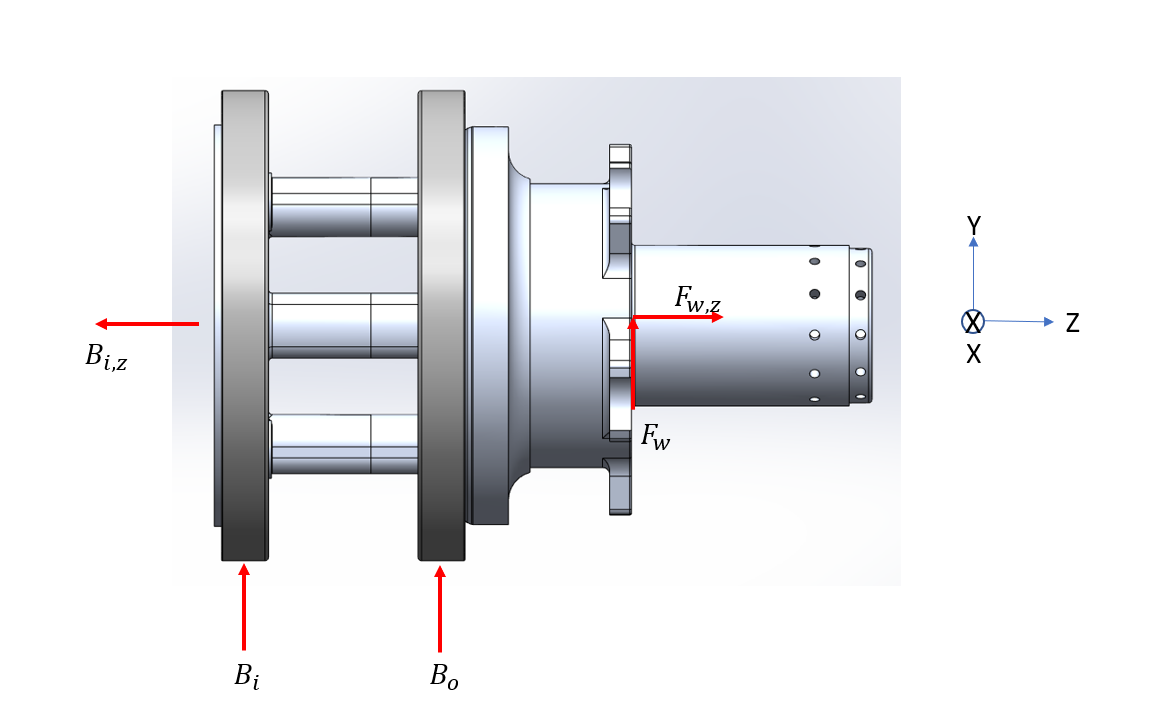

function cf = getFactors(f0,fA,C0)
    det = 2*f0*fA/C0;
    if det<=0.178
        factors = [0.38 0.72 1.65 2.39 0.92];
    elseif det<=0.357
        factors = [0.4 0.72 1.57 2.28 0.92];
    elseif det<=0.714
        factors = [0.43 0.72 1.46 2.11 0.92];
    elseif det<=1.07
        factors = [0.46 0.72 1.38 2 0.92];
    elseif det<=1.43
        factors = [0.47 0.72 1.34 1.93 0.92];
    elseif det<=2.14
        factors = [0.5 0.72 1.26 1.82 0.92];
    elseif det<=3.57
        factors = [0.55 0.72 1.14 1.66 0.92];
    else
        factors = [0.56 0.72 1.12 1.63 0.92];
    end

    cf.e = factors(1);
    cf.x2 = factors(2);
    cf.y1 = factors(3);
    cf.y2 = factors(4);
    cf.y0 = factors(5);
end

function P = getEqDynamicLoad(f,cf)
    fr = sqrt(f(1)^2+f(2)^2);
    fa = f(3);
    if fa/fr <= cf.e
        P = fr + cf.y1*fa;
    else
        P = cf.x2*fr+cf.y2*fa;
    end
end
